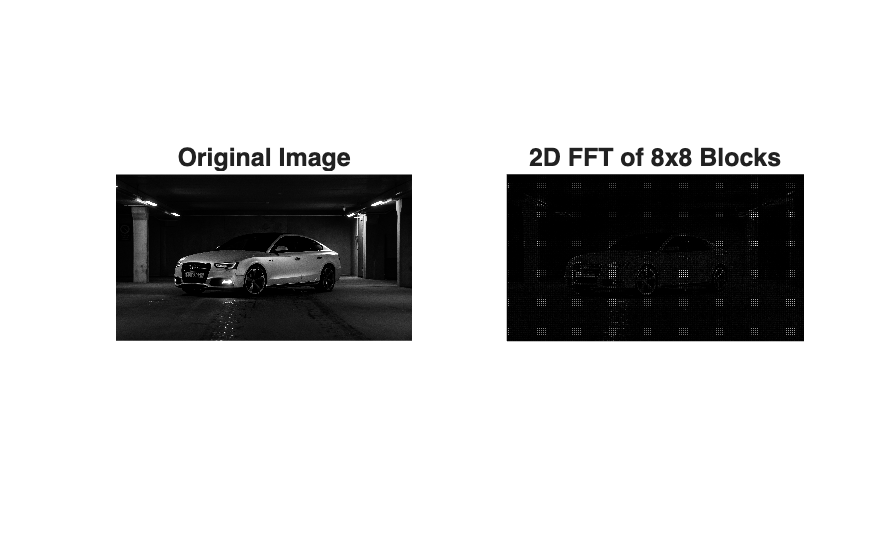

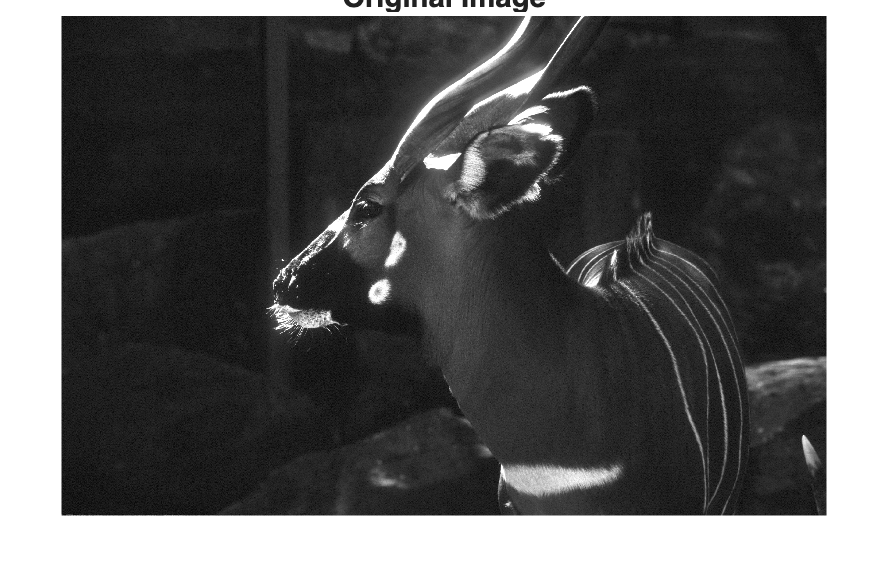

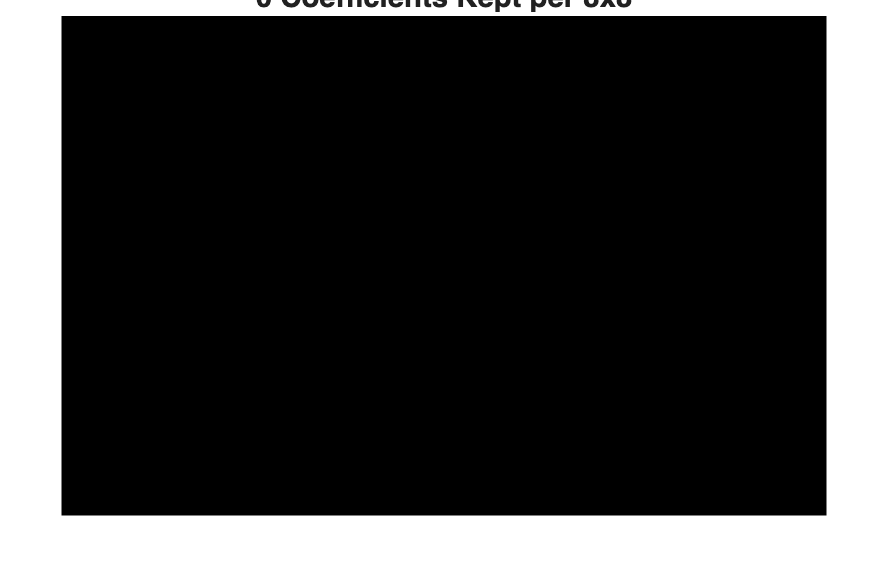

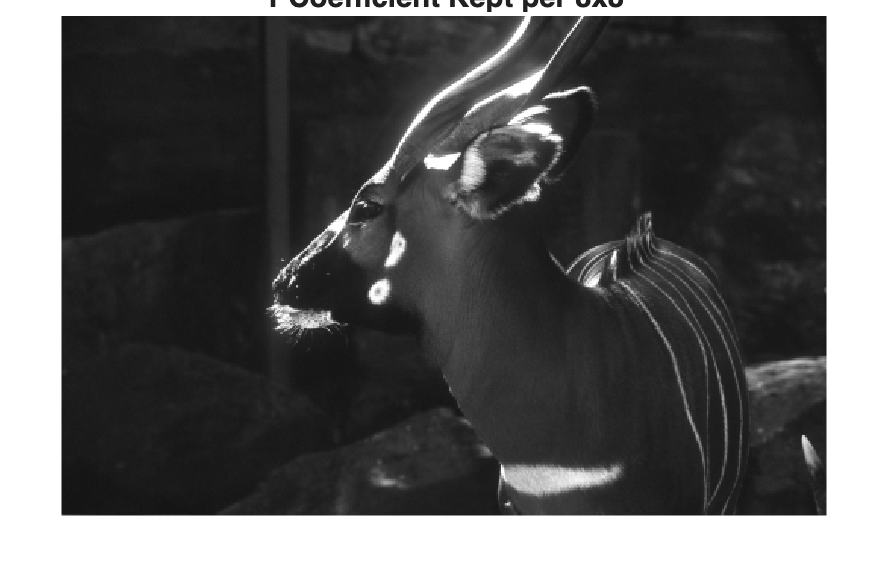

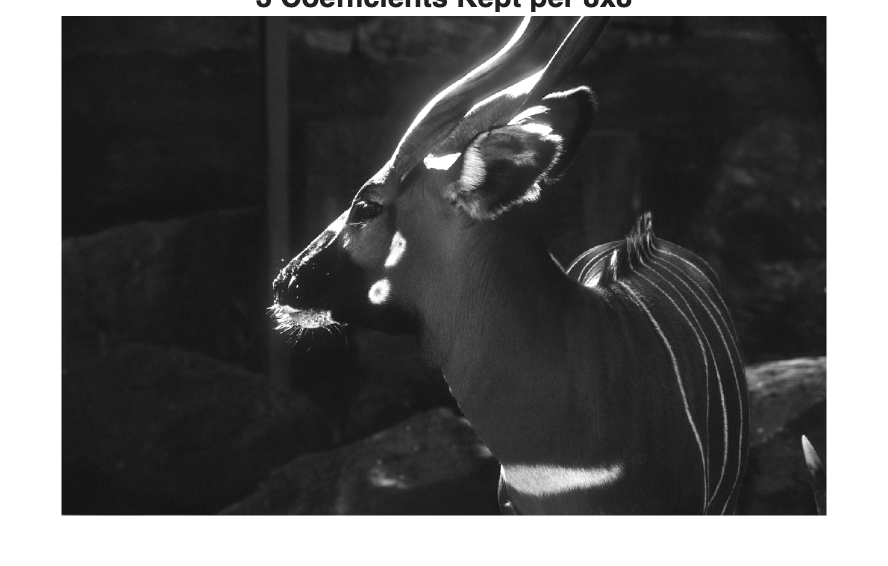

clear
% 1. Load a sample image and convert to grayscale/double
img = imread('theory/audi.jpeg'); % You can replace this with your own image
if size(img, 3) == 3
    img = rgb2gray(img);
end
img = im2double(img);


% 2. Define the block size
blockSize = [8 8];

% 3. Define the FFT function to apply to each block
% We use fft2, then fftshift to center the zero-frequency (DC) component.
% We take the magnitude with abs() and use log scale for better visualization.
fftProcess = @(block_struct) log(1 + abs(fftshift(fft2(block_struct.data))));

% 4. Apply the function to the image using blockproc
fft_img = blockproc(img, blockSize, fftProcess);

% 5. Display the results
figure;
subplot(1,2,1);
imshow(img);
title('Original Image');

subplot(1,2,2);
imshow(fft_img, []); % [] scales the display range automatically
title('2D FFT of 8x8 Blocks');